# 提取信号幅度差

## 读取文件

clear
close all
% 文件路径
% 315
dirName = 'D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压';
% 203
% dirName = 'D:\file\Lab-Drive\Project\GPS_Backscatter\Data\0612测试集_3Tag_35Point\Tag2_Loc11';

FileTable = [
'061mV_gnss_log_2021_06_07_21_46_16.txt';
'064mV_gnss_log_2021_06_07_21_36_52.txt';
'068mV_gnss_log_2021_06_07_21_25_25.txt';
'074mV_gnss_log_2021_06_07_21_15_36.txt';
'075mV_gnss_log_2021_06_07_20_33_05.txt';
'079mV_gnss_log_2021_06_07_20_51_28.txt';
'079mV_gnss_log_2021_06_07_20_58_37.txt';
'079mV_gnss_log_2021_06_07_21_05_30.txt';
'085mV_gnss_log_2021_06_07_20_42_40.txt';
'087mV_gnss_log_2021_06_07_21_55_58.txt';
'091mV_gnss_log_2021_06_07_22_06_59.txt';
'094mV_gnss_log_2021_06_07_22_16_12.txt';
'096mV_gnss_log_2021_06_07_22_24_08.txt';
'101mV_gnss_log_2021_06_07_22_31_47.txt';
'101mV_gnss_log_2021_06_07_22_40_44.txt';
'106mV_gnss_log_2021_06_07_22_51_24.txt';
'110mV_gnss_log_2021_06_07_23_02_21.txt';
'110mV_gnss_log_2021_06_08_09_36_47.txt';
'115mV_gnss_log_2021_06_08_09_52_22.txt';
'119mV_gnss_log_2021_06_08_10_00_38.txt';
'123mV_gnss_log_2021_06_08_10_08_49.txt';
'127mV_gnss_log_2021_06_08_10_17_44.txt';
'131mV_gnss_log_2021_06_08_10_24_43.txt';
'135mV_gnss_log_2021_06_08_10_32_47.txt';
'139mV_gnss_log_2021_06_08_10_39_38.txt';
'143mV_gnss_log_2021_06_08_10_47_09.txt';
'147mV_gnss_log_2021_06_08_10_56_19.txt';
'150mV_gnss_log_2021_06_08_11_02_39.txt';
'152mV_gnss_log_2021_06_08_16_34_58.txt';
'155mV_gnss_log_2021_06_08_11_18_30.txt';
'159mV_gnss_log_2021_06_08_11_32_31.txt';
'162mV_gnss_log_2021_06_08_11_38_36.txt';
'166mV_gnss_log_2021_06_08_11_47_02.txt';
'170mV_gnss_log_2021_06_08_11_56_08.txt';
'174mV_gnss_log_2021_06_08_12_01_58.txt';
'178mV_gnss_log_2021_06_08_12_10_38.txt';
'182mV_gnss_log_2021_06_08_12_16_23.txt';
'186mV_gnss_log_2021_06_08_12_24_31.txt';
'186mV_gnss_log_2021_06_08_15_13_18.txt';
'186mv_gnss_log_2021_06_08_15_25_02.txt';
'186mv_gnss_log_2021_06_08_15_30_02.txt';
'186mV_gnss_log_2021_06_08_15_38_35.txt';
'190mV_gnss_log_2021_06_08_15_51_58.txt';
'194mV_gnss_log_2021_06_08_16_01_06.txt';
'200mV_gnss_log_2021_06_08_16_08_11.txt';
'206mV_gnss_log_2021_06_08_16_15_28.txt';
'209mV_gnss_log_2021_06_08_16_22_21.txt';
];
Nfile = size(FileTable,1); 



## 解析文件名中的信息

NnameEle = 9;
Nnum = 7;
FileProperty = zeros(Nfile,Nnum);
for j=1:Nfile
    iNum = 1;
    fileName = FileTable(j,:);
    a = strsplit(fileName,'_');
    for i=1:NnameEle
        str = a{i};
        if ~isempty(find(isstrprop(str,'digit'),1))
            FileProperty(j,iNum) = str2double(str(isstrprop(str,'digit')));
            iNum = iNum + 1;
        end
    end
end
iV = 1; 
iYear = 2; iMonth = 3; iDay = 4;iHour = 5; iMin = 6; iSec = 7;

## 文件读取控制

% 循环读取
gnssAmplitude = zeros(Nfile,3*5);
for iFile = 1:Nfile
% prFileName = 'P12_150mV_100mV_Tag2_gnss_log_2021_06_12_21_15_30.txt';
prFileName = FileTable(iFile, :);

## 绘制载噪比

% Set the data filter and Read log file
% prFileName = 'P13_150mV_100mV_Tag2_gnss_log_2021_06_12_21_25_55.txt';
dataFilter = SetDataFilter;
[gnssRaw,gnssAnalysis] = ReadGnssLogger(dirName,prFileName,dataFilter);
if isempty(gnssRaw)
    continue
%     return, 
end

%% process raw measurements, compute pseudoranges:
[gnssMeas]= ProcessGnssMeasForBackscatter(gnssRaw);

%% plot pseudoranges and pseudorange rates
h1 = figure;
% [colors] = PlotPseudoranges(gnssMeas,prFileName);
% h2 = figure;
% PlotPseudorangeRates(gnssMeas,prFileName,colors);
% h3 = figure;
% PlotCno(gnssMeas,prFileName,colors);
colors = PlotCno(gnssMeas,prFileName);


Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/061mV_gnss_log_2021_06_07_21_46_16.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 35 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/064mV_gnss_log_2021_06_07_21_36_52.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 45 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/068mV_gnss_log_2021_06_07_21_25_25.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 43 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/074mV_gnss_log_2021_06_07_21_15_36.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 37 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/075mV_gnss_log_2021_06_07_20_33_05.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger

All measurements removed. Specify dataFilter less strictly than this:, 

ans = 3×1 cell 数组
    {'FullBiasNanos ~= 0'                   }
    {'ConstellationType==1'                 }
    {'bitand(State,2^0) & bitand(State,2^3)'}



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/079mV_gnss_log_2021_06_07_20_51_28.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger

All measurements removed. Specify dataFilter less strictly than this:, 

ans = 3×1 cell 数组
    {'FullBiasNanos ~= 0'                   }
    {'ConstellationType==1'                 }
    {'bitand(State,2^0) & bitand(State,2^3)'}



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/079mV_gnss_log_2021_06_07_20_58_37.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 76 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/079mV_gnss_log_2021_06_07_21_05_30.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 64 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/085mV_gnss_log_2021_06_07_20_42_40.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 60 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/087mV_gnss_log_2021_06_07_21_55_58.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 46 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/091mV_gnss_log_2021_06_07_22_06_59.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 4 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/094mV_gnss_log_2021_06_07_22_16_12.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 10 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/096mV_gnss_log_2021_06_07_22_24_08.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 8 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/101mV_gnss_log_2021_06_07_22_31_47.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 50 bad meas inside ProcessGnssMeas>FilterValid because:
towUnc > 500 ns
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/101mV_gnss_log_2021_06_07_22_40_44.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 78 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/106mV_gnss_log_2021_06_07_22_51_24.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 27 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/110mV_gnss_log_2021_06_07_23_02_21.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 76 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/110mV_gnss_log_2021_06_08_09_36_47.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 98 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/115mV_gnss_log_2021_06_08_09_52_22.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 75 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/119mV_gnss_log_2021_06_08_10_00_38.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 59 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/123mV_gnss_log_2021_06_08_10_08_49.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 59 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/127mV_gnss_log_2021_06_08_10_17_44.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 63 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/131mV_gnss_log_2021_06_08_10_24_43.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 98 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/135mV_gnss_log_2021_06_08_10_32_47.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 64 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/139mV_gnss_log_2021_06_08_10_39_38.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 29 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/143mV_gnss_log_2021_06_08_10_47_09.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 98 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/147mV_gnss_log_2021_06_08_10_56_19.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 97 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/150mV_gnss_log_2021_06_08_11_02_39.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 153 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/152mV_gnss_log_2021_06_08_16_34_58.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 171 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/155mV_gnss_log_2021_06_08_11_18_30.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 120 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/159mV_gnss_log_2021_06_08_11_32_31.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 67 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/162mV_gnss_log_2021_06_08_11_38_36.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 49 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/166mV_gnss_log_2021_06_08_11_47_02.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 54 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/170mV_gnss_log_2021_06_08_11_56_08.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 67 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/174mV_gnss_log_2021_06_08_12_01_58.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 95 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/178mV_gnss_log_2021_06_08_12_10_38.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 84 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/182mV_gnss_log_2021_06_08_12_16_23.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 60 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/186mV_gnss_log_2021_06_08_12_24_31.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 79 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/186mV_gnss_log_2021_06_08_15_13_18.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger

All measurements removed. Specify dataFilter less strictly than this:, 

ans = 3×1 cell 数组
    {'FullBiasNanos ~= 0'                   }
    {'ConstellationType==1'                 }
    {'bitand(State,2^0) & bitand(State,2^3)'}



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/186mv_gnss_log_2021_06_08_15_25_02.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger

All measurements removed. Specify dataFilter less strictly than this:, 

ans = 3×1 cell 数组
    {'FullBiasNanos ~= 0'                   }
    {'ConstellationType==1'                 }
    {'bitand(State,2^0) & bitand(State,2^3)'}



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/186mv_gnss_log_2021_06_08_15_30_02.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger

All measurements removed. Specify dataFilter less strictly than this:, 

ans = 3×1 cell 数组
    {'FullBiasNanos ~= 0'                   }
    {'ConstellationType==1'                 }
    {'bitand(State,2^0) & bitand(State,2^3)'}



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/186mV_gnss_log_2021_06_08_15_38_35.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 107 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/190mV_gnss_log_2021_06_08_15_51_58.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 32 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/194mV_gnss_log_2021_06_08_16_01_06.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 37 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/200mV_gnss_log_2021_06_08_16_08_11.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 31 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/206mV_gnss_log_2021_06_08_16_15_28.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 28 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\315单Tag改电压/209mV_gnss_log_2021_06_08_16_22_21.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 26 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s


## 提取最强信号

% 信号持续时间长，强度大，选取整个采样时段内平均值最强的信号
M = length(gnssMeas.Svid);
N = length(gnssMeas.FctSeconds);
iNan = find(isnan(gnssMeas.Cn0DbHz));
Cn0iDbHz = gnssMeas.Cn0DbHz;
Cn0iDbHz(iNan) = 0;
Ecn0 = mean(Cn0iDbHz);
[Esort,iMax] = sort(Ecn0,'descend');

Nmax = 2;
timeSeconds = gnssMeas.FctSeconds-gnssMeas.FctSeconds(1);% elapsed time in seconds
figure
for i=1:Nmax
    Cn0iDbHz = gnssMeas.Cn0DbHz(:,iMax(i));
    iF = find(isfinite(Cn0iDbHz));
    if ~isempty(iF)
        ti = timeSeconds(iF(end));
        h = plot(timeSeconds,Cn0iDbHz);
        hold on
        set(h,'Color',colors(iMax(i),:));
        ts = int2str(gnssMeas.Svid(iMax(i)));
        text(ti,Cn0iDbHz(iF(end)),ts,'Color',colors(iMax(i),:));
    end
end
Cn0iDbHz = gnssMeas.Cn0DbHz(:, [iMax(1) iMax(2)]);

## 计算强信号的幅度均值

% 根据信号强度分离出两条路径
trend = [ smooth(Cn0iDbHz(:,1), 21) smooth(Cn0iDbHz(:,2), 21)];
gnssCn0Extract = Cn0iDbHz - trend;
figure
plot(gnssCn0Extract)

iNan = find(isnan(gnssCn0Extract));
Cn0Extract = gnssCn0Extract;
Cn0Extract(iNan) = 0;
% pickUp -> backscattered sat signal  BKS
% pickDn -> original sat signal       NBKS
pickUp = zeros(N, Nmax);
pickDn = zeros(N, Nmax);
CnoSmooth = [smooth(Cn0Extract(:,1), 7) smooth(Cn0Extract(:,2), 7)];
for i=1:N
    for j=1:Nmax
        if isfinite(gnssCn0Extract(i,j)) 
            if Cn0Extract(i,j) > CnoSmooth(i,j)
                pickUp(i,j) = 1;
            else
                pickDn(i,j) = 1;
            end
        end
    end
end

% plot to check seperation
gnssMeaSep.iBks_1 = find(pickUp(:,1) == 1);
gnssMeaSep.iBks_2 = find(pickUp(:,2) == 1);
gnssMeasSep.Bks = pickUp .* Cn0Extract;
gnssMeaSep.iOrg_1 = find(pickDn(:,1) == 1); 
gnssMeaSep.iOrg_2 = find(pickDn(:,2) == 1);
gnssMeasSep.Org = pickDn .* Cn0Extract;
gnssMeasSep.smooth = CnoSmooth;

% 画出分类结果
figure
subplot(3,1,1)
h = plot(Cn0Extract);
colors = get(h,'Color');
subplot(3,1,2)
plot(Cn0Extract(:,1),'-*','Color',colors{1},'MarkerIndices',gnssMeaSep.iBks_1,'MarkerEdgeColor','r');
hold on
plot(gnssMeasSep.smooth(:,1),'c-')
plot(Cn0Extract(:,1),'-*','Color',colors{1},'MarkerIndices',gnssMeaSep.iOrg_1,'MarkerEdgeColor','g');
hold off

subplot(3,1,3)
plot(Cn0Extract(:,2),'-*','Color',colors{2},'MarkerIndices',gnssMeaSep.iBks_2,'MarkerEdgeColor','r');
hold on
plot(gnssMeasSep.smooth(:,2),'c-')
plot(Cn0Extract(:,2),'-*','Color',colors{2},'MarkerIndices',gnssMeaSep.iOrg_2,'MarkerEdgeColor','g');
hold off

close all

% 求出幅度均值
% Amplitude = zeros(1,2);
% Amplitude(1) = mean(gnssMeasSep.Bks(gnssMeaSep.iBks_1,1)) - mean(gnssMeasSep.Org(gnssMeaSep.iOrg_1,1));
% Amplitude(2) = mean(gnssMeasSep.Bks(gnssMeaSep.iBks_2,2)) - mean(gnssMeasSep.Org(gnssMeaSep.iOrg_2,2));

% 分割成五段，得到五个均值扩展
Amplitude = zeros(2,5);
NBksSeg = [floor(length(gnssMeaSep.iBks_1)/5) floor(length(gnssMeaSep.iBks_2)/5)];
NOrgSeg = [floor(length(gnssMeaSep.iOrg_1)/5) floor(length(gnssMeaSep.iOrg_2)/5)];

Amplitude(1,:) = mean(reshape(gnssMeasSep.Bks(gnssMeaSep.iBks_1(1:NBksSeg(1)*5),1),  NBksSeg(1),[])) ...
    - mean(reshape(gnssMeasSep.Org(gnssMeaSep.iOrg_1(1:NOrgSeg(1)*5),1),  NOrgSeg(1), []));
Amplitude(2,:) = mean(reshape(gnssMeasSep.Bks(gnssMeaSep.iBks_2(1:NBksSeg(2)*5),2),  NBksSeg(2),[])) ...
    - mean(reshape(gnssMeasSep.Org(gnssMeaSep.iOrg_2(1:NOrgSeg(2)*5),2),  NOrgSeg(2), []));



gnssAmplitude(iFile,:) = [reshape(Amplitude',1,[]) mean(Amplitude)];
end

% gnssAmplitude = mean(Amplitude);
 gnssDataRaw = [FileProperty gnssAmplitude];

## 画出电压与幅度的曲线图

% 拼接距离到幅度信息上
gnssData = zeros(size(gnssDataRaw));
iValid = 1;
for i=1:Nfile
    if gnssDataRaw(i,end) ~= zeros(1,5)
        gnssData(iValid,:) = gnssDataRaw(i,:); 
        iValid = iValid + 1;
    end
end
gnssData = gnssData(1:iValid-1,:);




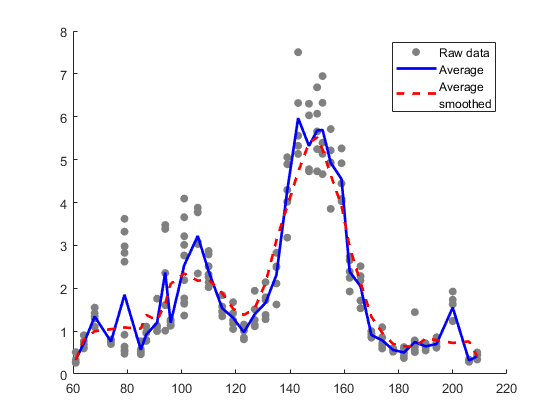



Nvalid = size(gnssData,1);
% choose = [1 2 7 8 9 10 14 18 19 24 31 37];
% choose = [1 2 7 8 22 27 33];
% choose = 1:6;
% plot(gnssData(choose,size(gnssData,2)), gnssData(choose,size(gnssData,2)-1), 'r+')

voltage = gnssData(:,1);
[voltage, Index] = sort(voltage);
Amp = gnssData(:,size(gnssData,2)-4:size(gnssData,2));
Amp = Amp(Index,:);

volTab = unique(voltage);
Nvol = length(volTab);
xvol = volTab;


AverAmp = zeros(Nvol,1);

for i=1:Nvol
    AmpTemp = Amp(find(voltage == volTab(i)),:);
    AverAmp(i) = mean(AmpTemp,'all');
end

AverAmpSmooth = smooth(AverAmp);

figure
hold on
plot(gnssData(:,1), gnssData(:,size(gnssData,2)-1), 'o','MarkerFaceColor',[0.50,0.50,0.50],'MarkerEdgeColor','none')
plot(gnssData(:,1), gnssData(:,size(gnssData,2)-2), 'o','MarkerFaceColor',[0.50,0.50,0.50],'MarkerEdgeColor','none')
plot(gnssData(:,1), gnssData(:,size(gnssData,2)-3), 'o','MarkerFaceColor',[0.50,0.50,0.50],'MarkerEdgeColor','none')
plot(gnssData(:,1), gnssData(:,size(gnssData,2)-4), 'o','MarkerFaceColor',[0.50,0.50,0.50],'MarkerEdgeColor','none')
h3=plot(gnssData(:,1), gnssData(:,size(gnssData,2)), 'o','MarkerFaceColor',[0.50,0.50,0.50],'MarkerEdgeColor','none');
h1=plot(xvol, AverAmp, '-','LineWidth',2,'Color','b');%,[0.93,0.69,0.13])
h2=plot(xvol, AverAmpSmooth, 'r--','LineWidth',2);

legend([h3 h1 h2],['Raw data'],'Average',['Average' newline 'smoothed'])
hold off